# Estadistica la venganza

## Importar datos

load("../../../Utils4SP/Datasets/S5_Estadistica101_LaVenganza.mat");

## Plots exploratorios

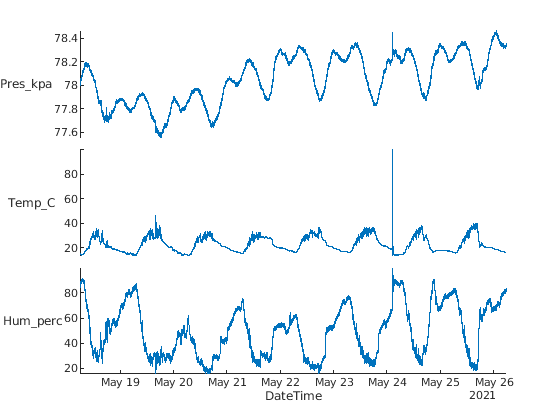

figure
stackedplot(atmosfera,'XVariable','DateTime')


summary(atmosfera)

Variables:

    Fecha: 137522×1 cell array of character vectors

    Hora: 137522×1 cell array of character vectors

    Pres_kpa: 137522×1 double

        Values:

            Min        77.55  
            Median     78.06  
            Max        78.46  

    Temp_C: 137522×1 double

        Values:

            Min             13.38  
            Median          21.01  
            Max             100    
            NumMissing      11     

    Hum_perc: 137522×1 double

        Values:

            Min             15.27  
            Median          50.16  
            Max             99.97  
            NumMissing      61     

    DateTime: 137522×1 datetime

        Values:

            Min       20210518 06:00:03
            Median    20210522 05:59:48
            Max       20210526 05:59:55




%Exploración de números faltantes
%Todos los lecturas de atmosfera
% Tal que existan NaN's en Su campo "Humedad"
% Y que sean todos los campos
atmosfera(ismissing(atmosfera.Hum_perc),:)

ans = 61×6 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc        DateTime     
    __________    ____________    ________    ______    ________    _________________

    {'210519'}    {'01:55:14'}     77.86      16.59       NaN       20210519 01:55:14
    {'210523'}    {'04:27:47'}      78.2      17.23       NaN       20210523 04:27:47
    {'210523'}    {'05:17:37'}      78.2       17.2       NaN       20210523 05:17:37
    {'210524'}    {'02:32:46'}     78.38        100       NaN       20210524 02:32:46
    {'210524'}    {'02:32:56'}     78.38        100       NaN       20210524 02:32:56
    {'210524'}    {'02:33:06'}     78.38        100       NaN       20210524 02:33:06
    {'210524'}    {'02:33:11'}     78.38        100       NaN       20210524 02:33:11
    


%Exploración de números faltantes
%Todos los lecturas de atmosfera
% Tal que existan NaN's en Su campo "Temperatura"
% Y que regrese todos los campos
atmosfera(ismissing(atmosfera.Temp_C),:)

ans = 11×6 table
      Fecha           Hora        Pres_kpa    Temp_C    Hum_perc        DateTime     
    __________    ____________    ________    ______    ________    _________________

    {'210518'}    {'17:59:58'}     77.71       NaN       49.68      20210518 17:59:58
    {'210520'}    {'09:27:14'}     77.95       NaN       38.97      20210520 09:27:14
    {'210520'}    {'09:37:27'}     77.95       NaN       39.47      20210520 09:37:27
    {'210520'}    {'21:22:43'}     77.84       NaN       44.84      20210520 21:22:43
    {'210521'}    {'20:50:27'}     78.04       NaN       48.07      20210521 20:50:27
    {'210522'}    {'20:57:34'}     78.07       NaN       51.34      20210522 20:57:34
    {'210522'}    {'20:57:44'}     78.08       NaN       51.21      20210522 20:57:44
    


%Exploración de números faltantes
%Todos los lecturas de atmosfera
% Tal que existan NaN's en Su campo "Temperatura"
% Y que regrese dateTime y Humedad
atmosfera(ismissing(atmosfera.Temp_C),["DateTime" "Hum_perc"])

ans = 11×2 table
        DateTime         Hum_perc
    _________________    ________

    20210518 17:59:58     49.68  
    20210520 09:27:14     38.97  
    20210520 09:37:27     39.47  
    20210520 21:22:43     44.84  
    20210521 20:50:27     48.07  
    20210522 20:57:34     51.34  
    20210522 20:57:44     51.21  
    20210522 20:58:39     51.29  
    20210523 10:19:08     53.71  
    20210523 21:44:54     52.82  
    20210525 18:14:48     61.06  


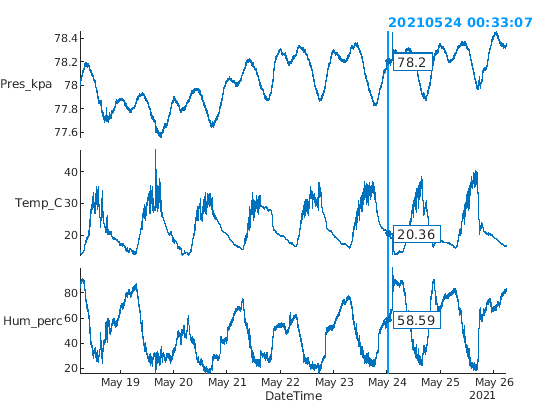


%Quitar NaNs
atmosfera_clean=rmmissing(atmosfera);

figure
stackedplot(atmosfera_clean,'XVariable','DateTime')

## Métricas de tendencia central

%Una gráfica con boxplot y histograma
figure
tiledlayout(1,2)
%subplot(1,2)
nexttile
%subplot(1,1,2)
boxplot(atmosfera_clean.Hum_perc)

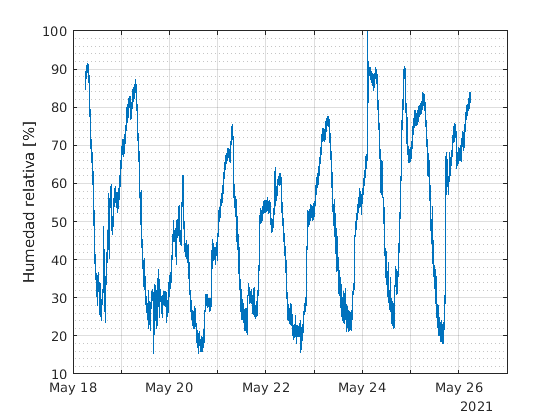

xlabel("Humedad relativa")
ylabel("%")

nexttile
%subplot(2,1,2)
histogram(atmosfera_clean.Hum_perc,'BinWidth',5,'Normalization',"probability")
xlabel("Humedad relativa [%]")
%ylabel("Cuentas")
ylabel("Probabilidad")


%Serie de tiempo
figure
plot(atmosfera_clean.DateTime,atmosfera_clean.Hum_perc)
ylabel("Humedad relativa [%]")
grid on
grid minor


%Mediana y promedio
%Promedio

- Calcular mediana, media y moda

- Colocarlos en línea verticales y horizonales en el histograma y series de tiempo

hum_mean=mean(atmosfera_clean.Hum_perc)

hum_mean = 49.6841

hum_median=median(atmosfera_clean.Hum_perc)

hum_median = 50.1550

hum_mode=mode(atmosfera_clean.Hum_perc)

hum_mode = 28.9200

%Cuantiles
%Primer cuartil
hum_1Q=quantile(atmosfera_clean.Hum_perc,0.25)

hum_1Q = 29.8800

hum_3Q=quantile(atmosfera_clean.Hum_perc,0.75)

hum_3Q = 66.9600

**Tarea para estos 5 minutos**

- Tercer cuartil

- Plotear la línea del 1Q y 3Q en el histograma y serie de tiempo

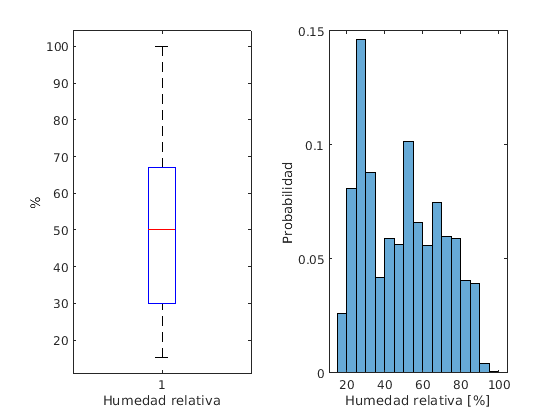




%Una gráfica con boxplot y histograma
figure
tiledlayout(1,2)
%subplot(1,2)
nexttile
%subplot(1,1,2)
boxplot(atmosfera_clean.Hum_perc)

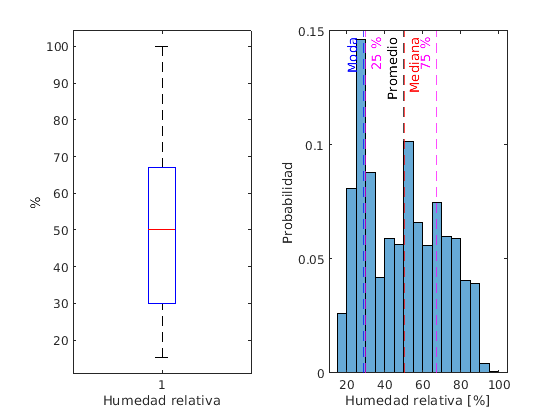

xlabel("Humedad relativa")
ylabel("%")

nexttile
%subplot(2,1,2)
histogram(atmosfera_clean.Hum_perc,'BinWidth',5,'Normalization',"probability")
hold on
xline(hum_median,'--r','Mediana')
xline(hum_mean,'--k','Promedio',"LabelHorizontalAlignment","left")
xline(hum_mode,'--b','Moda',"LabelHorizontalAlignment","left")
xline(hum_1Q,'--m','25 %',"LabelHorizontalAlignment","right")
xline(hum_3Q,'--m','75 %',"LabelHorizontalAlignment","left")
hold off


xlabel("Humedad relativa [%]")
%ylabel("Cuentas")
ylabel("Probabilidad")


%Matplotlib lo hace nativamente
%plot(x,y,'linecolor',[ 1 2 6])
%plot(x,y,'linecolor',rgb('navyblue'))

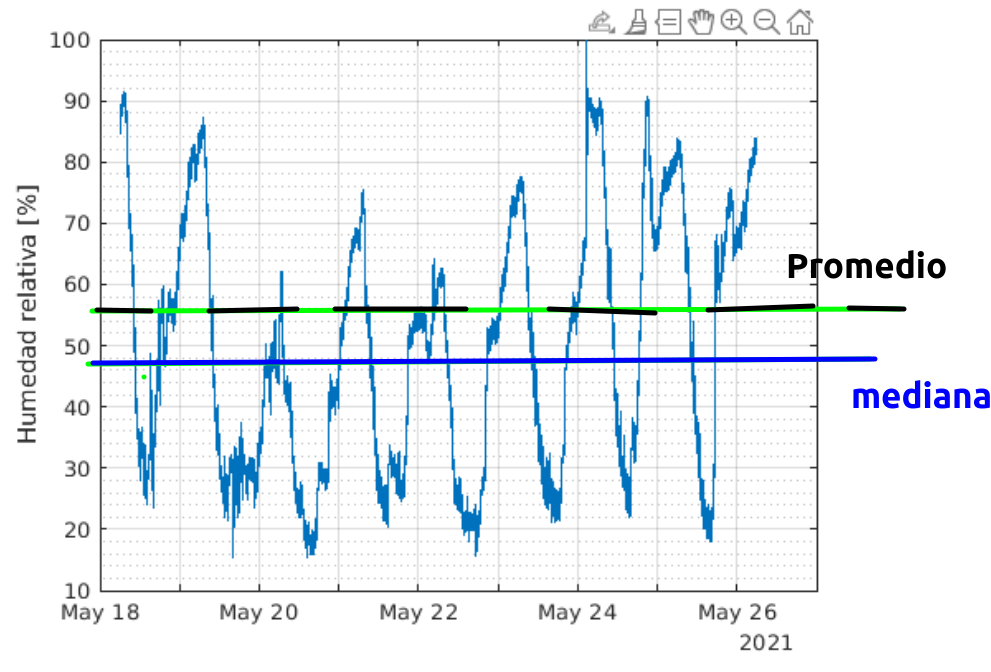

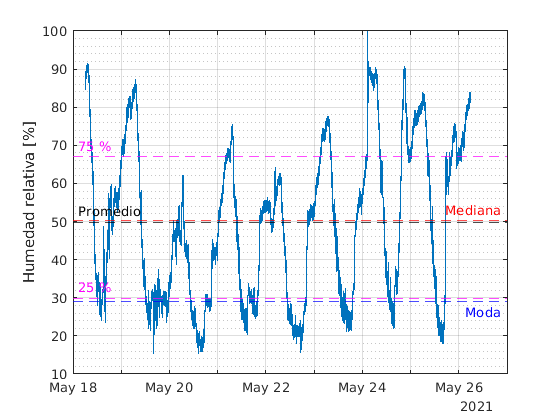

%Serie de tiempo
figure
plot(atmosfera_clean.DateTime,atmosfera_clean.Hum_perc)
hold on
yline(hum_median,'--r','Mediana')
yline(hum_mean,'--k','Promedio',"LabelHorizontalAlignment","left")
yline(hum_mode,'--b','Moda',"LabelVerticalAlignment","bottom")
yline(hum_1Q,'--m','25 %',"LabelHorizontalAlignment","left")
yline(hum_3Q,'--m','75 %',"LabelHorizontalAlignment","left")

hold off

ylabel("Humedad relativa [%]")
grid on
grid minor

## Dispersión

buho_left=buho(:,1);
plot(buho_left)

%Una gráfica con boxplot y histograma
figure
tiledlayout(1,2)
%subplot(1,2)
nexttile
%subplot(1,1,2)
boxplot(buho_left)

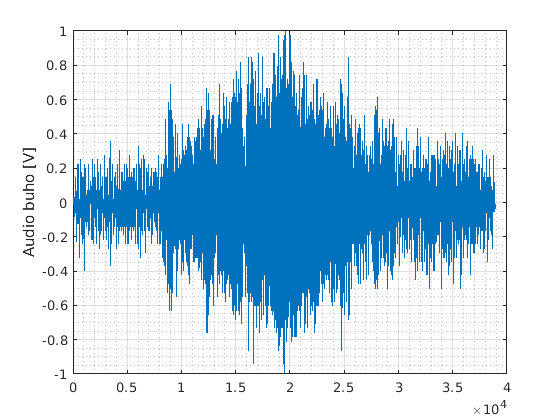

xlabel("Audio buho")
ylabel("V")

nexttile
%subplot(2,1,2)
histogram(buho_left,20,'Normalization',"probability")
xlabel("Audio buho [V]")
%ylabel("Cuentas")
ylabel("Probabilidad")


%Serie de tiempo
figure
plot(buho_left)
ylabel("Audio buho [V]")
grid on
grid minor

- Sacar dev est y var y promedio

- Colocar promedio

- Colocar promedio + $\sigma$ y promedio -$\sigma$

buho_var=var(buho_left) %V^2

buho_var = 0.0451

buho_std=std(buho_left) %V

buho_std = 0.2124

buho_mean=mean(buho_left) %V

buho_mean = 8.1547e-08

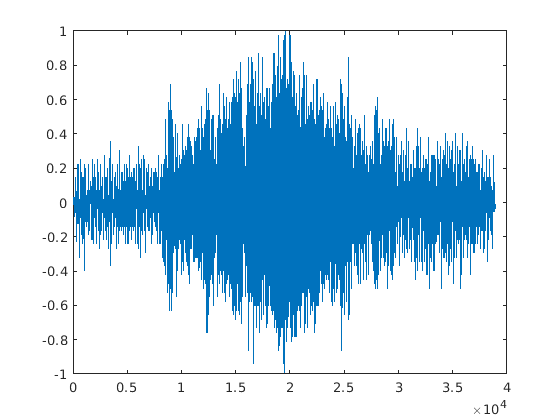

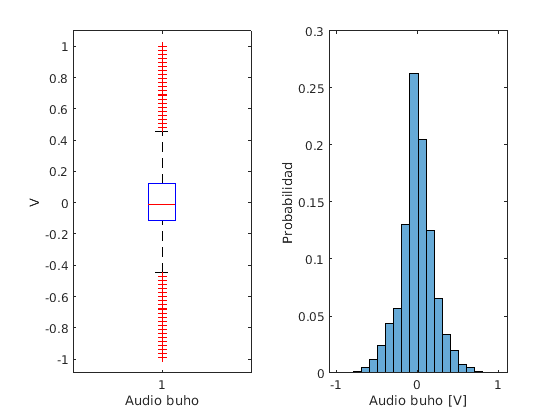


% var(2.*buho_left) %V^2
% std(2.*buho_left) %V
% 
% 
% 2*buho_var
% 2*buho_std

%Una gráfica con boxplot y histograma
figure
tiledlayout(1,2)
%subplot(1,2)
nexttile
%subplot(1,1,2)
boxplot(buho_left)

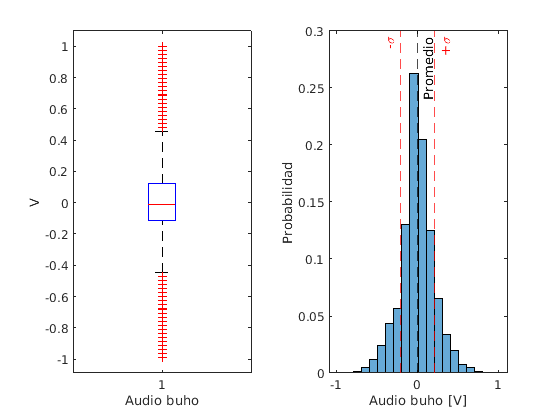

xlabel("Audio buho")
ylabel("V")

nexttile
%subplot(2,1,2)
histogram(buho_left,20,'Normalization',"probability")
hold on
xline(buho_mean,'k--','Promedio')
xline(buho_mean+buho_std,'r--','+\sigma')
xline(buho_mean-buho_std,'r--','-\sigma','LabelHorizontalAlignment',"left")
hold off
xlabel("Audio buho [V]")
%ylabel("Cuentas")
ylabel("Probabilidad")

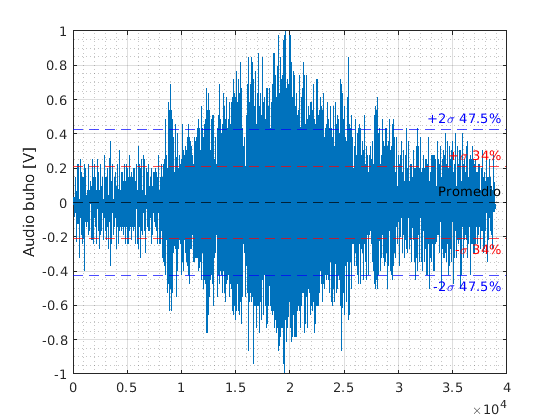



%Serie de tiempo
figure
plot(buho_left)
hold on
yline(buho_mean,'k--','Promedio')
yline(buho_mean+buho_std,'r--','+\sigma 34%')
yline(buho_mean-buho_std,'r--','-\sigma 34%','LabelVerticalAlignment',"bottom")
yline(buho_mean+2.*buho_std,'b--','+2\sigma 47.5%')
yline(buho_mean-2.*buho_std,'b--','-2\sigma 47.5%','LabelVerticalAlignment',"bottom")
hold off
ylabel("Audio buho [V]")
grid on
grid minor

## Ajustes

plot(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'.')
xlabel("Temperatura [C]")
ylabel("Humedad [%]")
grid on

[fit_realacion,gof]=fit(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'poly1')

fit_realacion =      Linear model Poly1:
     fit_realacion(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =      -2.772  (-2.781, -2.763)
       p2 =       113.2  (112.9, 113.4)

gof = struct with fields:
           sse: 1.5967e+07
       rsquare: 0.7212
           dfe: 137448
    adjrsquare: 0.7212
          rmse: 10.7783



[fit_realacion_2,gof]=fit(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'poly2')

fit_realacion_2 =      Linear model Poly2:
     fit_realacion_2(x) = p1*x^2 + p2*x + p3
     Coefficients (with 95% confidence bounds):
       p1 =       0.088  (0.08654, 0.08946)
       p2 =      -7.097  (-7.169, -7.024)
       p3 =       162.6  (161.8, 163.5)

gof = struct with fields:
           sse: 1.4498e+07
       rsquare: 0.7468
           dfe: 137447
    adjrsquare: 0.7468
          rmse: 10.2703


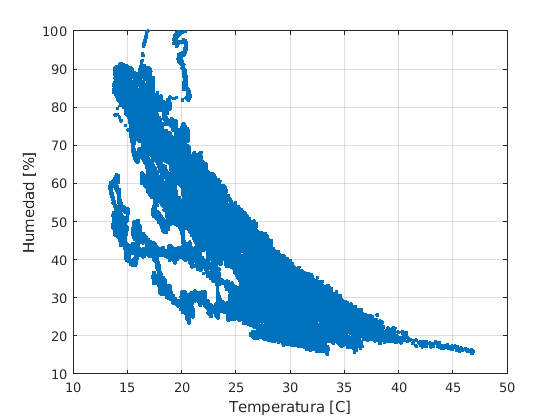


figure
plot(atmosfera_clean.Temp_C,atmosfera_clean.Hum_perc,'.')
hold on
plot(fit_realacion,'r')
plot(fit_realacion_2,'b')

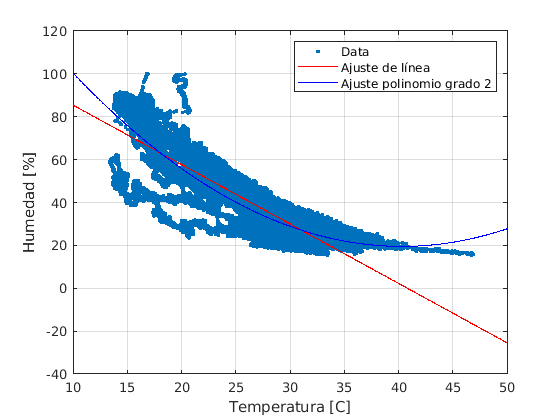

hold off
xlabel("Temperatura [C]")
ylabel("Humedad [%]")
legend("Data","Ajuste de línea","Ajuste polinomio grado 2")
grid on